# Entropic flux balance analysis

## **Author: Ronan Fleming, University of Galway**

## INTRODUCTION

Entropic flux balance analysis [1] maximises the (unnormalised) entropy of unidirectional fluxes ($$v_f$$ and $$v_r$$) and optionally a linear function of external net fluxes $$w$$, subject to mass balance constraints, optionally coupling constraints, box constraints on net flux, and zero lower bounds on unidirectional fluxes. This ensures that predicted steady state fluxes are thermodynamically feasible, assuming one is given a model that admits a thermodynamically feasible flux. A method for finding the largest subset of a given model that admits a thermodynamically feasible flux is described in this paper [3] and this tutorial [4]. Given a generic model of metabolism and context-specific omics data, this paper [5] and this tutorial [6] explain how to extract a context-specific model that admits a thermodynamically feasible internal net flux vector, using the XomicsToModel protocol [5].

Entropic flux balance analysis is mathematically represented by the optimisation problem


$$\min_ {v_{f},v_{r},w} v_{f}^{T} \cdot (\log(v_{f}) -1) + v_{r}^{T}\cdot (\log(v_{r}) -1) + c_{e}^{T} \cdot w 
\\
\text{subject  to}
\\
\quad v = [v_{f}-v_{r}; w ]
\\
\quad N\cdot(v_{f}-v_{r})+B\cdot w=b,  \quad  :y_{N}
\\
\quad C\cdot(v_{f}-v_{r})\leq d, \quad \quad \quad \quad   :y_{C}
\\
\quad l\leq v  \leq u, \quad  \quad \quad \quad \quad \quad \quad :z_{v}\\
\quad 0\leq v_{f,} \quad \quad \quad \quad \quad \quad \quad \quad :z_{v_{f}}\\
\quad  0\leq v_{r}, \quad \quad \quad \quad \quad \quad \quad \quad  :z_{v_{r}}
\\
\end{aligned}
$$


where N is the internal reaction stoichiometric matrix (all reactions bass balanced), B is the external reaction stoichiometric matrix (all reactions mass imbalanced), b may be used to represent any known fixed input (negative) or output (positive) of molecular species from the system, and zero otherwise. The variables to the right of the : are the corresponding dual variables to each constraint.

A variation of this is quadratically constrained entropic flux balance analysis [2], which allows one to penalise deviation of predicted net flux from experimentally measured net flux. This is represented by the following optimisation problem


$$\min_ {v_{f},v_{r},w} v_{f}^{T} \cdot (\log(v_{f}) -1) + v_{r}^{T}\cdot (\log(v_{r}) -1) + c_{e}^{T} \cdot w + \frac{1}{2}(v-h)^{T}\cdot H\cdot(v-h)
\\
\text{subject  to}
\\
\quad v = [v_{f}-v_{r}; w ]
\\
\quad N\cdot(v_{f}-v_{r})+B\cdot w=b,  \quad  :y_{N}
\\
\quad C\cdot(v_{f}-v_{r})\leq d, \quad \quad \quad \quad   :y_{C}
\\
\quad l\leq v  \leq u, \quad  \quad \quad \quad \quad \quad \quad :z_{v}\\
\quad 0\leq v_{f,} \quad \quad \quad \quad \quad \quad \quad \quad :z_{v_{f}}\\
\quad  0\leq v_{r}, \quad \quad \quad \quad \quad \quad \quad \quad  :z_{v_{r}}
\\
\end{aligned}
$$


where $H$ may be used to add penalties, e.g., $H_{j,j} = \frac{1}{(1+\sigma_{exp}^{2})} \text{ where } \sigma_{exp}\in\mathbb{R}_{\ge0}^{n}$  is the standard deviation in measured net flux $h$. 

## MATERIALS - EQUIPMENT SETUP

Mosek installation required

## PROCEDURE

Set the directory for results

basePath='~/work/sbgCloud';
resultsDirectory=[basePath '/programModelling/projects/thermoModel/results/entropicFBA'];

Set the model to load

modelToUse='iDopaNeuro';
%modelToUse='ecoli_core';
%modelToUse = 'fork';
%modelToUse = 'single';
%modelToUse='recon3';

if ~exist('model','var')
    switch modelToUse
        case 'single'
            driver_singleModel
        case 'fork'
            driver_forkModel

        case 'ecoli_core'
            dataDirectory=[basePath '/data'];
            load([dataDirectory '/models/published/e_coli_core.mat']);
            if ~isfield(model,'SConsistentMetBool') || ~isfield(model,'SConsistentRxnBool')
                massBalanceCheck=0;
                [~, ~, ~, ~, ~, ~, model, ~] = findStoichConsistentSubset(model, massBalanceCheck, 0);
            end
            model.lb(ismember(model.rxns,'BIOMASS_Ecoli_core_w_GAM'))=0.1;
            
        case 'recon3'
            %COBRA.models/mat/Recon3DModel_301_xomics_input.mat
            load(which('Recon3DModel_301_xomics_input.mat'))

            %change onto uMol/gDW/hr
            model.lb = model.lb;
            model.ub = model.ub;
        case 'iDopaNeuro'
            %load('~/drive/sbgCloud/projects/iDopaNeuro/results/codeResults/iDN1/iDopaNeuroC/iDopaNeuroC.mat')
            load('~/drive/sbgCloud/projects/variationalKinetics/data/iDopaNeuro/iDopaNeuroC.mat')
            model = iDopaNeuroC;
            clear iDopaNeuroC
            model.lb(ismember(model.rxns,'ATPM')) = model.lb(ismember(model.rxns,'ATPM'))/2;

            %problematic reactions
%             {'34DHPHEt'}      {'3, 4-Dihydroxy-L-Phenylalanine Transport' }      -0.53635    0     {'34dhphe[e]  <=> 34dhphe[c] '}
%             {'URAt'    }      {'Uracil Transport via Faciliated Diffusion'}    -0.0013626    0     {'ura[e]  <=> ura[c] '        }
            model.lb(ismember(model.rxns,'34DHPHEt'))=-1e4;
            model.ub(ismember(model.rxns,'34DHPHEt'))= 1e4;
            model.lb(ismember(model.rxns,'URAt'))=-1e4;
            model.ub(ismember(model.rxns,'URAt'))= 1e4;
    end
end

Examine the constraints on the model

printConstraints(model,-1e4,1e4,model.SIntRxnBool)

    Forward_Reaction, 0 bound                                  Name                                  lb      ub                                                              equation                                                        
    _________________________    ________________________________________________________________    __    _______    _______________________________________________________________________________________________________________________

    {'10FTHF6GLUtl'         }    {'6-Glutamyl-10Fthf Transport, Lysosomal'                      }    0       10000    {'10fthf6glu[c]  -> 10fthf6glu[l] '                                                                                   }
    {'1PPDCRp'              }    {'Delta1-Piperideine-2-Carboxylate Reductase, Perixosomal'     }    0       10000 

printConstraints(model,-1e4,1e4,~model.SIntRxnBool)

    Forward_Reaction, 0 bound                                Name                                 lb     ub              equation         
    _________________________    _____________________________________________________________    __    _____    _________________________

     {'EX_34dhoxpeg[e]'    }     {'Exchange of 3, 4-Dihydroxyphenylethyleneglycol '          }    0     10000    {'34dhoxpeg[e]  -> '    }
     {'EX_3mlda[e]'        }     {'Exchange of 3-Methylimidazoleacetic Acid '                }    0     10000    {'3mlda[e]  -> '        }
     {'EX_adrnl[e]'        }     {'Exchange of Adrenaline '                                  }    0     10000    {'adrnl[e]  -> '        }
     {'EX_amp[e]'          }     {'Exchange of AMP '                                         }    0     10000    {'amp[e]  -> '       

printCouplingConstraints(model,1);

           coupledRxnId                                               constraints                                    
    ___________________________    __________________________________________________________________________________

    {'Phosphatidylcholine'    }    {'PCHOLP_hs + PLA2_2 + SMS >= 2.025'                                             }
    {'Adenosine Monophosphate'}    {'AMPDA + NTD7 >= 0.2265'                                                        }
    {'Glutamate'              }    {'- ALATA_L + GLUCYS + GLUDxm + GLUDym - ASPTA - ILETA - LEUTA - VALTA >= 1.2225'}
    {'Aspartate'              }    {'ARGSS + ASPTA >= 1.1925'                                                       }
    {'Serine'                 }    {'GHMT2r + r0060 >= 0.8625'                                                      }
    {'Arginine'               }    {'GLYAMDTRc + r0145 >= 0.7245'                                        

Set the data parameters for the entropic flux balance analysis problem

Linear optimisation direction

model.osenseStr = 'min';

Reaction parameters

model.cf=0.1;
model.cr=0.1;
model.g=2;
if 0
    quad = zeros(size(model.S,2),1);
    quad(~model.SIntRxnBool)=1;
    model.Q=diag(quad);
end

## Reaction parameters

Setting the bounds on reaction direction is important, because certain bounds may be incompatible with the existence of a thermodynamically feasible steady state

`param.internalNetFluxBounds = 'original' `maintains direction and magnitude of internal net flux from model.lb & model.ub

`param.internalNetFluxBounds = 'directional'` maintains direction of internal net flux from model.lb & model.ub but not magnitude

`param.internalNetFluxBounds = 'none'` removes lower and upper bounds on internal net flux

`param.internalNetFluxBounds = 'random'`   random internal net flux direction, replacing constraints from model.lb & model.ub

param.internalNetFluxBounds='directional';
%param.internalNetFluxBounds='original';
%param.internalNetFluxBounds='none';

Maximum permitted internal flux

param.maxUnidirectionalFlux=100;
%model.vfl = [0;0;0]

## Method parameters

param.method='fluxes';
%param.method='fluxConc';%param.method='fluxConcNorm';

## Metabolite parameters (only relevant if a concentration method chosen)

Standard chemical potential

model.u0 = ones(1,size(model.S,1))*0;

Strictly positive weight on concentration entropy maximisation

model.f=1;

Scalar maximum permitted metabolite concentration

param.maxConc=1;

## Solver parameters

Set the solver

%param.solver='pdco';
param.solver='mosek';

Minimum permitted internal flux required for exponential cone reformulation

if strcmp(param.solver,'mosek')
    param.minUnidirectionalFlux=0;
end

Tolerances

param.feasTol=1e-7;

Printing level

param.printLevel=2; 
param.debug = 1;

## Entropic flux balance analysis

[solution,modelOut] = entropicFluxBalanceAnalysis(model,param);

Using directional internal net flux bounds only.
Using existing external net flux bounds without modification.

MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 2965            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 3625            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 1219
Eliminator terminated.
Linear dependency checker started.
Linear dependenc

model=modelOut;

Extract the fields of the solution structure

if solution.stat ~=1
    disp('No solution')
    return
end
[v,vf,vr,vt,y_N,z_v,z_dx,z_vf,z_vr,stat]=...
    deal(solution.v,solution.vf,solution.vr,solution.vt,solution.y_N,solution.z_v,solution.z_dx,solution.z_vf,solution.z_vr,solution.stat);
cf = model.cf;
cr = model.cr;

g=deal(model.g);
if isfield(solution,'x')
    [x, x0, z_x, z_x0, z_dx] = deal(solution.x, solution.x0, solution.z_x, solution.z_x0, solution.z_dx);
    [u0,f]=deal(model.u0,model.f);
    dx = x - x0;
end

 Extract the internal (N) and exchange (B) stoichiometric matrices  

N = model.S(:,model.SConsistentRxnBool);
B = model.S(:,~model.SConsistentRxnBool);

Extract the matrix of coupling constraints, if present

if isfield(model,'C')
    C = model.C(:,model.SConsistentRxnBool);
    y_C = solution.y_C;
end

Extract the objective on the internal reaction rates

e   = ones(length(vf),1);
ci = solution.osense*model.c(model.SConsistentRxnBool);

Extract the net internal reaction dual variable

z_vi = z_v(model.SConsistentRxnBool);

Compute the nullspace of the internal stoichiometric matrix

if 0
   %get nullspace of N
    [Z,rankS]=getNullSpace(N,0);
else
    Z=[];
end

### ANTICIPATED RESULTS

Optimality conditions should be satisfied approximately to the feasibility (or optimality) tolerances of the numerical optimisation solver, typically 1e-6.

if param.printLevel>2 || 1
    v_detailed=1;
else
    v_detailed=0;
end

Biochemical optimality conditions: steady state

if isfield(solution,'x')
    fprintf('%8.2g %s\n',norm(N*(vf - vr) - x + x0 - model.b,inf), '|| N*(vf - vr) - x + x0 - b ||_inf');
else
    fprintf('%8.2g %s\n',norm(model.S*v - model.b,inf), '|| S*v - b ||_inf');
end

 2.8e-07 || S*v - b ||_inf


Optionally, display detailed properties of flux related solution vector

if v_detailed
    fprintf('%8.2g %s\n',sum(vf)+sum(vr),'sum(vf)+sum(vr) >= 0');
    fprintf('%8.2g %s\n',norm(g.*reallog(vf),inf),'|| g*log(vf) ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr),inf),'|| g*log(vr) ||_inf');
    fprintf('%8.2g %s\n',norm(cr,inf),'|| cr ||_inf');
    fprintf('%8.2g %s\n',norm(cf,inf),'|| cf ||_inf');
    fprintf('%8.2g %s\n',norm(ci,inf),'|| ci ||_inf');
    fprintf('%8.2g %s\n',norm(N'*y_N,inf),'|| N''*y_N ||_inf');
    fprintf('%8.2g %s\n',norm(z_v,inf),'|| z_v ||_inf');
    fprintf('%8.2g %s\n',norm(z_vf,inf),'|| z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(z_vr,inf),'|| z_vr ||_inf');
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(C'*y_C,inf),'|| C''*y_C ||_inf');
    end
end

 4.1e+03 sum(vf)+sum(vr) >= 0


      31 || g*log(vf) ||_inf


      13 || g*log(vr) ||_inf


     0.1 || cr ||_inf


     0.1 || cf ||_inf


       0 || ci ||_inf


 1.4e+02 || N'*y_N ||_inf


 1.4e+02 || z_v ||_inf


   2e-07 || z_vf ||_inf


      35 || z_vr ||_inf


      37 || C'*y_C ||_inf


if isfield(model,'C')
    fprintf('%8.2g %s\n',norm(g.*reallog(vf) + ci + cf + N'*y_N + C'*y_C + z_vi + z_vf,inf), '|| g*log(vf) + ci + cf + N''*y_N + C''*y_C + z_vi + z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr) - ci + cr - N'*y_N - C'*y_C - z_vi + z_vr,inf),'|| g*log(vr) - ci + cr - N''*y_N - C''*y_C - z_vi + z_vr ||_inf');
    fprintf('%8.2g %s\n',norm(   C'*y_C + z_vi + z_vf,inf), '||  + C''*y_C + z_vi + z_vf ||_inf');
    fprintf('%8.2g %s\n',norm( - C'*y_C - z_vi + z_vr,inf),'||  - C''*y_C - z_vi + z_vr ||_inf');
else
    fprintf('%8.2g %s\n',norm(g.*reallog(vf) + ci + cf + N'*y_N + z_vi - z_vf,inf), '|| g*log(vf) + ci + cf + N''*y_N + z_vi - z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr) - ci + cr - N'*y_N - z_vi - z_vr,inf),'|| g*log(vr) - ci + cr - N''*y_N - z_vi - z_vr ||_inf');
end

      16 || g*log(vf) + ci + cf + N'*y_N + C'*y_C + z_vi + z_vf ||_inf


       2 || g*log(vr) - ci + cr - N'*y_N - C'*y_C - z_vi + z_vr ||_inf


 1.4e+02 ||  + C'*y_C + z_vi + z_vf ||_inf


 1.4e+02 ||  - C'*y_C - z_vi + z_vr ||_inf


Derived biochemical optimality conditions (fluxes)

if isfield(model,'C')
    res = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*C'*y_C - 2*z_vi - z_vr + z_vf;
    fprintf('%8.2g %s\n',norm(res,inf),'|| g*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*C''*y_C - 2*z_vi - z_vr + z_vf ||_inf');
else
    res = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*z_vi - z_vr + z_vf;
    fprintf('%8.2g %s\n',norm(res,inf),'|| g*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*z_vi - z_vr + z_vf ||_inf');
end

      88 || g*log(vr/vf) + cr - cf - 2*ci - 2*N'*y_N - 2*C'*y_C - 2*z_vi - z_vr + z_vf ||_inf


Optionally, display detailed properties of concentration related solution vector

if isfield(solution,'x')
    fprintf('\n%s\n','Optimality conditions (concentrations)')
    if v_detailed
        fprintf('%8.2g %s\n',norm(reallog(x),inf), '|| log(x)||_inf');
        fprintf('%8.2g %s\n',norm(u0,inf), '|| u0 ||_inf');
        fprintf('%8.2g %s\n',norm(y_N,inf), '|| y_N ||_inf');
        fprintf('%8.2g %s\n',norm(z_dx,inf), '|| z_dx ||_inf');
        fprintf('%8.2g %s\n',norm(z_x,inf), '|| z_x ||_inf');
        fprintf('%8.2g %s\n',norm(z_x0,inf), '|| z_x0 ||_inf');
    end
    fprintf('%8.2g %s\n',norm(f.*reallog(x) + u0 - y_N + z_dx + z_x,inf), '|| f.*log(x) + u0 - y_N + z_dx + z_x ||_inf');
    fprintf('%8.2g %s\n',norm(f.*reallog(x0) + u0 + y_N - z_dx + z_x0,inf),'|| f.*log(x0) + u0 + y_N - z_dx + z_x0 ||_inf');

    fprintf('\n%s\n','Derived biochemical optimality conditions (concentrations)')
    fprintf('%8.2g %s\n',norm(f.*reallog(x./x0) - 2*y_N + 2*z_dx + z_x - z_x0,inf),'|| f.*log(x/x0) - 2*y_N + 2*z_dx + z_x - z_x0 ||_inf');
    fprintf('%8.2g %s\n',norm(f.*reallog(x.*x0) + 2*u0 + z_x + z_x0,inf),'|| f.*log(x.*x0) + 2*u0 + z_x + z_x0 ||_inf');


    fprintf('\n%s\n','Derived biochemical optimality conditions (fluxes and concentrations)')
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(g.*reallog(vf) + cf + ci + N'*(u0 + f.*reallog(x) + z_dx + z_x) + C'*y_C + z_v + z_vf,inf),'|| g*log(vf) + cf + ci + N''*(u0 + f*log(x) + z_dx + z_x) + C''*y_C + z_v + z_vf ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr) + cr - ci - N'*(u0 + f.*reallog(x) + z_dx + z_x) - C'*y_C - z_v + z_vr,inf), '|| g*log(vr) + cr - ci - N''*(u0 + f*log(x) + z_dx + z_x) - C''*y_C - z_v +  z_vr ||_inf');
    else
        fprintf('%8.2g %s\n',norm(g.*reallog(vf) + cf + ci + N'*(u0 + f.*reallog(x) + z_dx + z_x) + z_v + z_vf,inf),'|| g*log(vf) + cf + ci + N''*(u0 + f*log(x) + z_dx + z_x) + z_v + z_vf ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr) + cr - ci - N'*(u0 + f.*reallog(x) + z_dx + z_x) - z_v + z_vr,inf),'|| g*log(vr) + cr - ci - N''*(u0 + f*log(x) + z_dx + z_x) - z_v + z_vr ||_inf');
    end

    fprintf('\n%s\n','Derived biochemical optimality conditions (fluxes and concentrations)')
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*C'*y_C - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + C''*y_C + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*C'*y_C - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + C''*y_C + z_v) - z_vf + z_vr ||_inf');
    else
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr.*vf) + cr + cf - N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + z_v) - z_vf + z_vr ||_inf');
    end
end

fprintf('\n')
if isfield(solution,'v')
    vfpad = NaN*ones(size(model.S,2),1);
    vfpad(model.SConsistentRxnBool)=vf;
    vrpad = NaN*ones(size(model.S,2),1);
    vrpad(model.SConsistentRxnBool)=vr;
    zvfpad = NaN*ones(size(model.S,2),1);
    zvfpad(model.SConsistentRxnBool)=z_vr;
    zvrpad = NaN*ones(size(model.S,2),1);
    zvrpad(model.SConsistentRxnBool)=z_vr;
    T1 = table(model.lb, v,model.ub,z_v,vfpad,zvfpad,vrpad,zvrpad,'VariableNames',{'vl','v','vu','z_v','vf','z_vf','vr','z_vr'});
    if length(v)<=10
        disp(T1)
    end
end


if isfield(solution,'x') 
    T2 = table(model.xl,solution.x,model.xu,z_x,model.x0l,x0,model.x0u,z_x0,model.dxl,dx,model.dxu,z_dx,...
        'VariableNames',{'xl' 'x' 'xu' 'z_x' 'x0l' 'x0' 'x0u' 'z_x0' 'dxl' 'dx' 'dxu' 'z_dx'});
    if length(solution.x)<=10
        disp(T2)
    end
end

### *TROUBLESHOOTING*

### Debugging satisfaction of constraints 

Entropic Flux Balance Analysis will find a thermodynamically feasible steady state, provided one exists. That is, bounds on net fluxes, for example those causing net flux around a stoichiometrically balanced cycle, can preclude the existince of a thermodynamically feasible steady state. The following plots can be used to investigate deviation from thermodynamic feasibility for certain reactions, indicated by numerical tolerances beyond that considered satifactory (typically 1e-6 for a double precision solver). Setting the bounds on reaction direction is important, because certain bounds may be incompatible with the existence of a thermodynamically feasible steady state

`param.internalNetFluxBounds = 'original' `maintains direction and magnitude of internal net flux from model.lb & model.ub

`param.internalNetFluxBounds = 'directional'` maintains direction of internal net flux from model.lb & model.ub but not magnitude

`param.internalNetFluxBounds = 'none'` removes lower and upper bounds on internal net flux

`param.internalNetFluxBounds = 'random'`   random internal net flux direction, replacing constraints from model.lb & model.ub

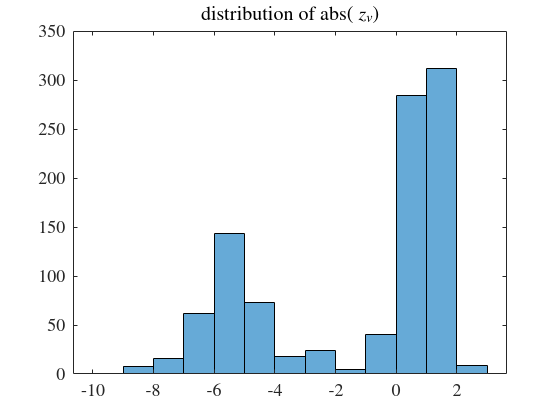

l = model.lb(model.SConsistentRxnBool);
u = model.ub(model.SConsistentRxnBool);
vi = vf - vr;
logvrvf = reallog(vr./vf);

figure
histogram(log10(abs(z_v)))
title('distribution of abs( $z_v$)')

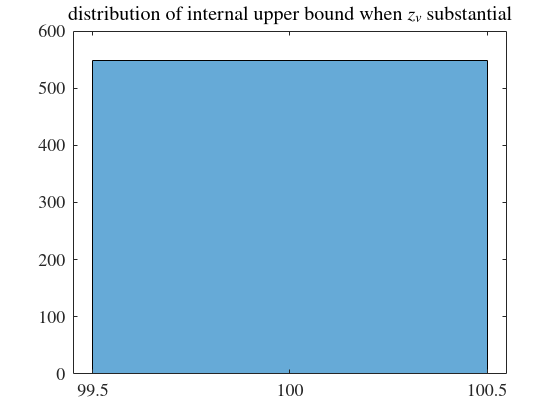


zBool = abs(z_vi)>0.1;
if any(l(zBool)~=0)
    figure
    histogram(l(zBool))
    title('distribution of internal lower bound when  $z_v$ substantial')
end
if any(u(zBool)~=inf)
    figure
    histogram(u(zBool))
    title('distribution of internal upper bound when $z_v$ substantial')
end

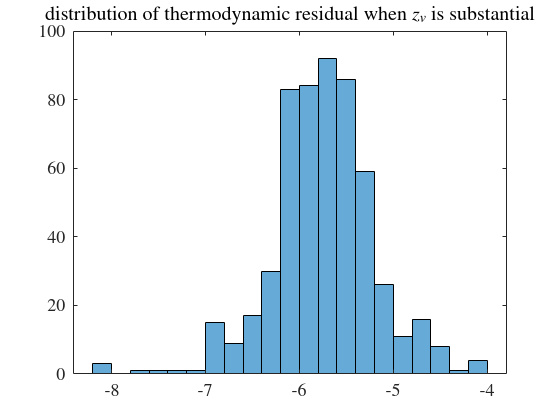


if any(zBool)
    figure
    histogram(log10(abs(res(zBool))))
    title('distribution of thermodynamic residual when $z_v$ is substantial')
end

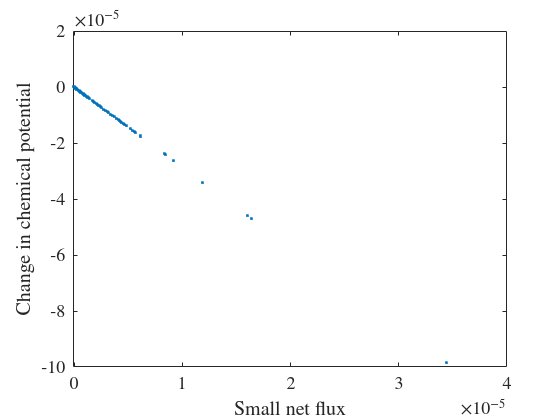

if any(zBool)
    figure
    plot(vi(zBool),logvrvf(zBool),'.')
    xlabel('Small net flux')
    ylabel('Change in chemical potential')
end

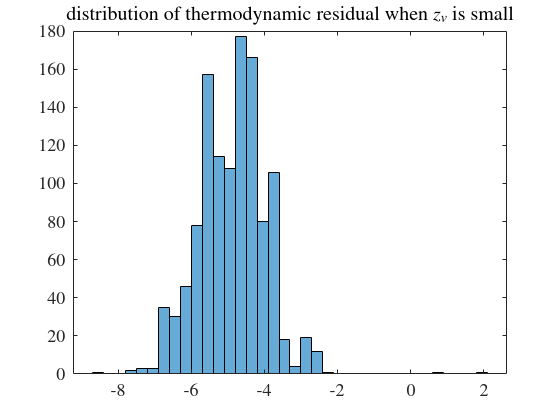


if any(~zBool)
    %thermo residual is large even when z_v is small
    figure
    histogram(log10(abs(res(~zBool))))
    title('distribution of thermodynamic residual when $z_v$ is small')
end

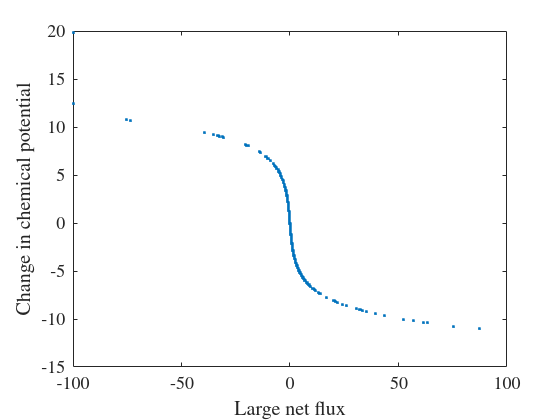

if any(~zBool)
    figure
    plot(vi(~zBool),logvrvf(~zBool),'.')
    xlabel('Large net flux')
    ylabel('Change in chemical potential')
end

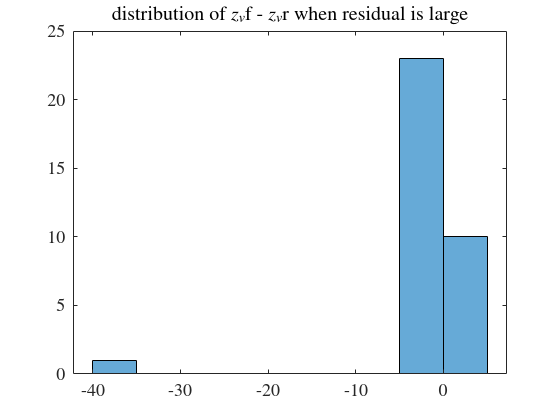

rBool = abs(res)>0.001;
fwdBool = vi>0;
if any(rBool)
    ab = z_vf - z_vr;
    figure
    histogram(ab(rBool))
    title('distribution of $z_v$f - $z_v$r when residual is large')
end

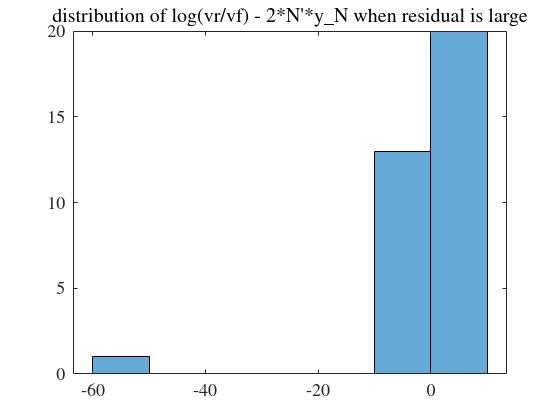

if any(rBool)
    %deviation from thermodynamic constraint occuring when net flux is
    %substantial
    figure
    res1 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N;
    histogram(res1(rBool))
    title('distribution of log(vr/vf) - 2*N''*y\_N when residual is large')
end

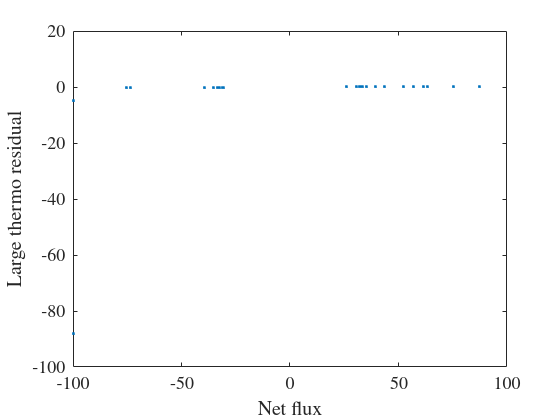

if any(rBool)
    figure
    plot(vi(rBool),res(rBool),'.')
    xlabel('Net flux')
    ylabel('Large thermo residual')
end

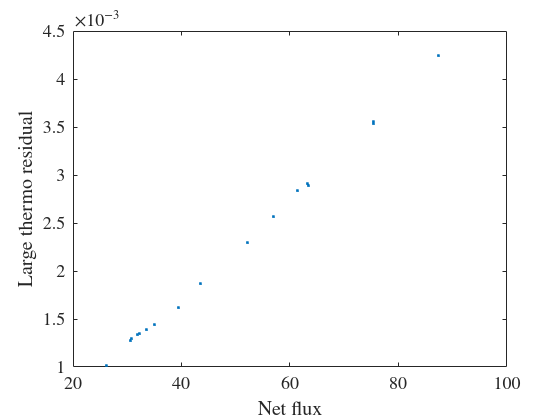

if any(rBool)
    figure
    plot(vi(rBool & fwdBool),res(rBool & fwdBool),'.')
    xlabel('Net flux')
    ylabel('Large thermo residual')
end

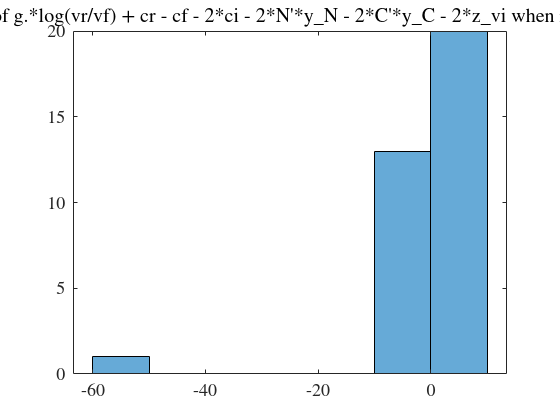

if any(rBool)
    figure
    if isfield(model,'C')
        res5 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*C'*y_C - 2*z_vi;
        histogram(res5(rBool))
        title('distribution of g.*log(vr/vf) + cr - cf - 2*ci - 2*N''*y\_N - 2*C''*y\_C - 2*z\_vi when residual is large')
    else
        res5 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*z_vi;
        histogram(res5(rBool))
        title('distribution of g.*log(vr/vf) + cr - cf - 2*ci - 2*N''*y\_N - 2*z\_vi when residual is large')
    end
end

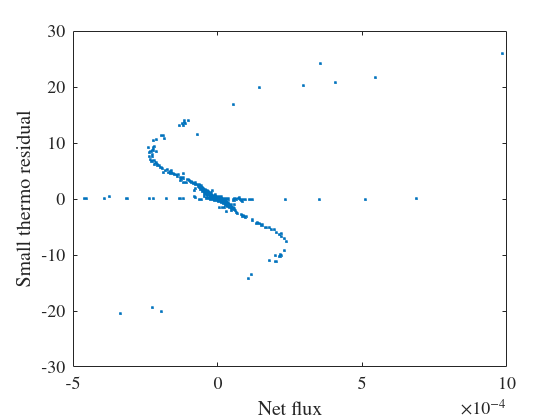

if any(~rBool)
    figure
    plot(res(~rBool),vi(~rBool),'.')
    xlabel('Net flux')
    ylabel('Small thermo residual')
end

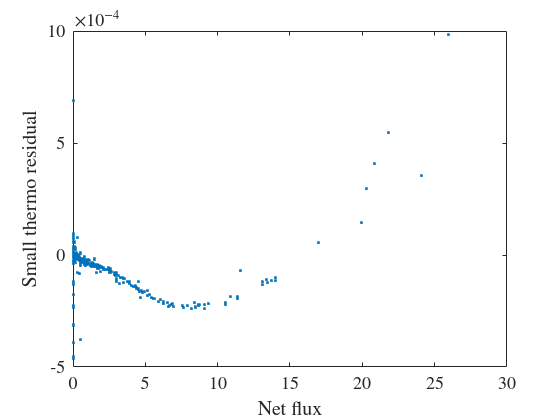

if any(rBool)
    figure
    plot(vi(~rBool & fwdBool),res(~rBool & fwdBool),'.')
    xlabel('Net flux')
    ylabel('Small thermo residual')
end

if isequal(modelToUse,'single') && isfield(solution,'x')
    fprintf('%8.2g %s\n',norm(vf - exp(-(cf + cr - u0(1) - u0(2))/2)*x(1)), '|| vf - exp(-(cr + cf - u0 - u0)/2)*x1 ||')
end

##  Quadratically constrained entropic flux balance analysis - all external reactions

Generate a random external flux vector that is a perturbation of the previously obtained external flux vector and then quadratically penalise any deviation from it.

model.h = (solution.v).*(rand(length(solution.v),1)+0.5)*2;

Do not optimise toward any internal net flux

model.h(model.SConsistentRxnBool)=NaN;

Compare the original external flux vector, with the external flux vector to peanlise deviation from

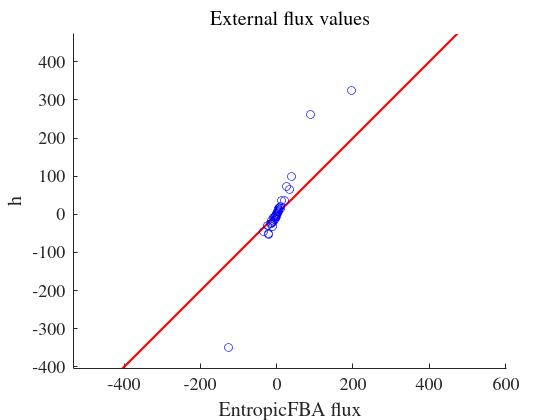

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(~model.SConsistentRxnBool),model.h(~model.SConsistentRxnBool),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('h')
title('External flux values')
axis equal

Set the penaltiy

HH = ones(length(solution.v),1);
HH(model.SConsistentRxnBool)=0;
model.H = spdiags(HH,0,length(solution.v),length(solution.v));

Run the optimisation

[solutionQEFBA,modelOut] = entropicFluxBalanceAnalysis(model,param);

Using directional internal net flux bounds only.
Using existing external net flux bounds without modification.

MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3170            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 3830            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 1219
Eliminator terminated.
Linear dependency checker started.
Linear dependenc

Compare the original external flux vector, with the quadratically constrained external flux vector. The values should be closer to the red line than above, but not exactly, because the quadratic penalty is trading off against entropy maximisation of internal reactions. Change H(j,j) to adjust this trade off.

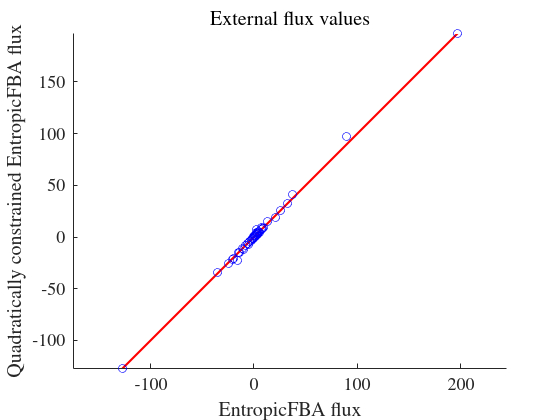

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(~model.SConsistentRxnBool),solutionQEFBA.v(~model.SConsistentRxnBool),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('Quadratically constrained EntropicFBA flux')
title('External flux values')
axis equal

## Quadratically constrained entropic flux balance analysis - subset of external reactions

Generate a random given external flux vector that is a perturbation of the previously obtained external flux vector and then quadratically penalise any deviation from it.

model.h = (solution.v).*(rand(length(solution.v),1)+0.5)*2;

Do not optimise toward any internal net flux

model.h(model.SConsistentRxnBool)=NaN;

Only optimise toward the top 10 magnitude given external net flux

[sortedh,ind]=sort(abs(model.h),'descend','MissingPlacement','last');
if length(ind)>10
    model.h(ind(11:end))=NaN;
end

Compare the original external flux vector, with the external flux vector to peanlise deviation from

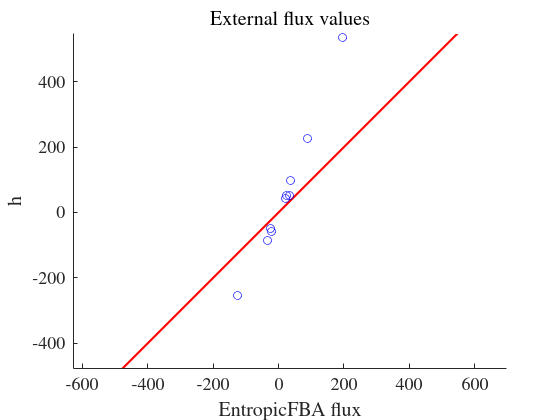

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(isfinite(model.h)),model.h(isfinite(model.h)),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('h')
title('External flux values')
axis equal

Set the penaltiy

HH = ones(length(solution.v),1);
HH(model.SConsistentRxnBool)=0;
model.H = spdiags(HH,0,length(solution.v),length(solution.v));

Run the optimisation

[solutionQEFBA,modelOut] = entropicFluxBalanceAnalysis(model,param);

Using directional internal net flux bounds only.
Using existing external net flux bounds without modification.

MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 2975            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 3635            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 1219
Eliminator terminated.
Linear dependency checker started.
Linear dependenc

Compare the original external flux vector, with the quadratically constrained external flux vector. The values should be closer to the red line than above, but not exactly, because the quadratic penalty is trading off against entropy maximisation of internal reactions. Change H(j,j) to adjust this trade off.

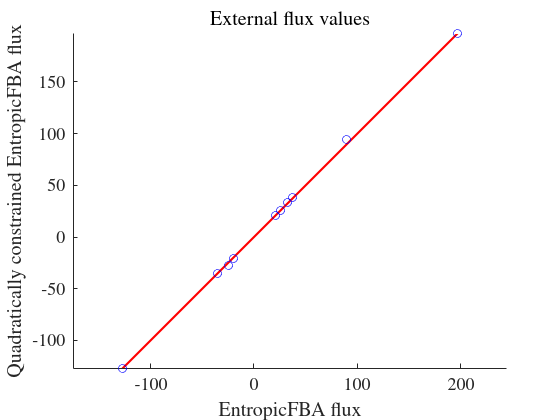

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(isfinite(model.h)),solutionQEFBA.v(isfinite(model.h)),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('Quadratically constrained EntropicFBA flux')
title('External flux values')
axis equal

## Quadratically constrained entropic flux balance analysis - subset of external reactions and no coupling constraints

model = rmfield(model,{'C','d'});

Generate a random given external flux vector that is a perturbation of the previously obtained external flux vector and then quadratically penalise any deviation from it.

model.h = (solution.v).*(rand(length(solution.v),1)+0.5)*2;

Do not optimise toward any internal net flux

model.h(model.SConsistentRxnBool)=NaN;

Only optimise toward the top 10 magnitude given external net flux

[sortedh,ind]=sort(abs(model.h),'descend','MissingPlacement','last');
if length(ind)>10
    model.h(ind(11:end))=NaN;
end

Compare the original external flux vector, with the external flux vector to peanlise deviation from

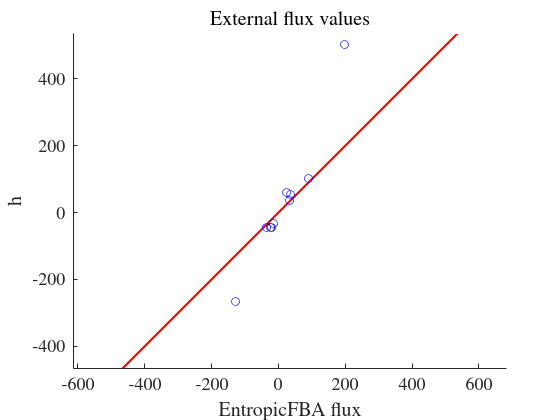

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(isfinite(model.h)),model.h(isfinite(model.h)),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('h')
title('External flux values')
axis equal

Set the penaltiy

HH = ones(length(solution.v),1);
HH(model.SConsistentRxnBool)=0;
model.H = spdiags(HH,0,length(solution.v),length(solution.v));

Run the optimisation

[solutionQEFBA,modelOut] = entropicFluxBalanceAnalysis(model,param);

Using directional internal net flux bounds only.
Using existing external net flux bounds without modification.

MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 12:12:35)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 2964            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 3635            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 1218
Eliminator terminated.
Linear dependency checker started.
Linear dependenc

Compare the original external flux vector, with the quadratically constrained external flux vector. The values should be closer to the red line than above, but not exactly, because the quadratic penalty is trading off against entropy maximisation of internal reactions. Change H(j,j) to adjust this trade off.

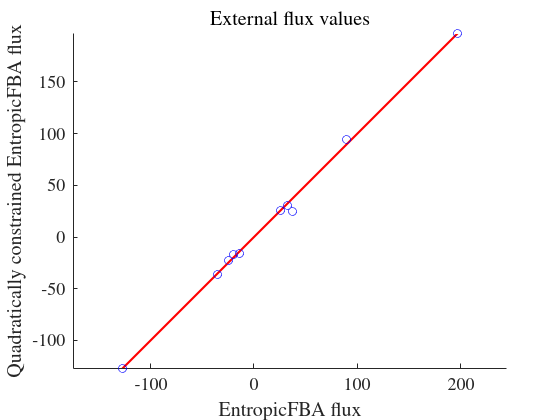

figure
hold on
fplot(@(x) x, 'LineWidth', 1.5,'Color','r')
plot(solution.v(isfinite(model.h)),solutionQEFBA.v(isfinite(model.h)),'o','Color','b')
xlabel('EntropicFBA flux')
ylabel('Quadratically constrained EntropicFBA flux')
title('External flux values')
axis equal

## *Acknowledgments*

Co-funded by the European Union's Horizon Europe Framework Programme (101080997)

## REFERENCES

[1] Fleming, R. M. T., Maes, C. M., Saunders, M. A., Ye, Y., and Palsson, B. O., "A variational principle for computing nonequilibrium fluxes and potentials in genome-scale biochemical networks", *Journal of Theoretical Biology* 292 (2012), pp. 71--77.

[2] Preciat, German and Moreno, Edinson Lucumi, "Mechanistic model-driven exometabolomic characterisation of human dopaminergic neuronal metabolism", *bioRxiv* (2022). [https://www.biorxiv.org/content/10.1101/2021.11.08.467803v2](https://www.biorxiv.org/content/10.1101/2021.11.08.467803v2) 

[3] Ronan M T Fleming, Hulda S Haraldsdottir, Le Hoai Minh, Phan Tu Vuong, Thomas Hankemeier, Ines Thiele, Cardinality optimization in constraint-based modelling: application to human metabolism, *Bioinformatics*, Volume 39, Issue 9, September 2023, btad450, [https://doi.org/10.1093/bioinformatics/btad450](https://doi.org/10.1093/bioinformatics/btad450)

[4] Ronan M T Fleming, Subset of a model that admits a thermodynamically consistent flux  [https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_findThermoConsistentFluxSubset.html](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_findThermoConsistentFluxSubset.html) 

[5] German Preciat, Agnieszka B. Wegrzyn, Xi Luo, Ines Thiele,Thomas Hankemeier,Ronan M.T. Fleming, XomicsToModel: Omics data integration and generation of thermodynamically consistent metabolic models, Nature Protocols (to appear) Biorxiv v2  [https://www.biorxiv.org/content/10.1101/2021.11.08.467803v2](https://www.biorxiv.org/content/10.1101/2021.11.08.467803v2) 

[6] German Preciat,  Extraction of context-specific models via XomicsToModel [https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_XomicsToModel.html](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_XomicsToModel.html) 